# Web Scraping 

***Please note**** that running these cells will create a "NBA.txt" file which is required to run subsequent cells, which will create a "clean.csv".*

In this lesson, you will learn about another method data scientists use to collect large amounts of data. Along with APIs, web scraping is a technique commonly used to scrape data from websites, forums, social media platforms, and other online sources. Web scraping is done by writing scripts or using existing tools to extract relevant information. 

One useful function for web scraping with MATLAB is **webread()**. The **webread()** function is used to read the data directly into MATLAB as a character array. The function **webread()** requires a URL as an input.

## Read the URL

In the example, below you will extract NBA player statistics from the following website: [NBA Stats](https://sports.yahoo.com/nba/stats/individual/?guccounter=1&guce_referrer=aHR0cHM6Ly93d3cuZ29vZ2xlLmNvbS8&guce_referrer_sig=AQAAACcxyP0zC_9xC_p4e21LXs0wPttsnh6LxuXVlCf1z8wm6XQpZteIS2bcNpDoLUonhbzw2m0f3n84C3CE3gjICj-10Dk4VjkE4yr9QO7PvfdK_GXYMeh0-ltK9H1O4bpHkJyO1uwGKfWNYY4pe_sM4C9718DyR4q8wKLl9SWtyMpN)

%clear the workspace and command window
clc;clear;

% Retrieve the HTML content from the website using its URL
NBA = webread(['https://sports.yahoo.com/nba/stats/individual/' ...
    '?guccounter=1&guce_referrer=aHR0cHM6Ly93d3cuZ29vZ2xlLmNvbS8&guce_referrer_' ...
    'sig=AQAAACcxyP0zC_9xC_p4e21LXs0wPttsnh6LxuXVlCf1z8wm6XQpZteIS2bcNpDoLUonhbzw2m0f3n84C3CE3gjICj' ...
    '-10Dk4VjkE4yr9QO7PvfdK_GXYMeh0-ltK9H1O4bpHkJyO1uwGKfWNYY4pe_sM4C9718DyR4q8wKLl9SWtyMpN'])

NBA =     '<!DOCTYPE html><html class="ys-design desktop" id="atomic" lang="en-US"><head><script>window.performance && window.performance.mark && window.performance.mark('PageStart');</script><meta http-equiv="content-type" content="text/html; charset=UTF-8"/><title>NBA  Leaders & Player Stats  - Yahoo Sports</title><meta name="keywords" content="NBA, National Basketball Association"/><meta http-equiv="X-UA-Compatible" content="IE=edge"/><meta http-equiv="x-dns-prefetch-control" content="on"/><link rel="canonical" href="https://sports.yahoo.com/nba/stats/individual/"/><meta property="og:image" content="https://s.yimg.com/it/api/res/1.2/Nm.Q9ktBFq1bB8joIv0bCw--~A/YXBwaWQ9eW5ld3M7dz0xMjAwO2g9NjMwO3E9MTAw/https://s.yimg.com/cv/apiv2/social/images/yahoo_default_logo.png"/><meta property="og:image:height" content="1200"/><meta property="og:image:width" content="630"/><link rel="dns-prefetch" href="//s.yimg.com"/><link rel="dns-prefetch" href="//b.scorecardresearch.com"/><link rel="dns-p

## Extract Text from HTML 

If you look at the variable **NBA** in its current state you will only see HTML content. At this point, you have to look through HTML content to locate the table and the specific elements containing the player's statistics. Let's extract the text from the variable **NBA **using the function **extractHTMLText().**

% Extract text from the variable NBA and store it in a variable called text
text = extractHTMLText(NBA)

text =     'Qualified Leaders  
     
     Qualified Status  Qualified Leaders   All Players   
     
     NBA  
     
     NBA   Eastern   Western   
     
     All Positions  
     
     All Positions   Point Guard   Shooting Guard   Guard   Guard-Forward   Small Forward   Power Forward   Forward   Forward-Center   Center   
     
     All Splits/Situations  
     
     Situations  All Splits/Situations   Home   Away   Day   Night   Pre-All Star   Post-All Star   In Wins   In Losses   Vs. Own Division   Vs. Own Conference   0 Days Rest   1 Day Rest   2 Days Rest   3+ Days Rest   
     
     Player  Team  G  Min  FGM  FGA  FG%  3PM  3PA  3P%  FTM  FTA  FT%  OR  DR  Reb  Ast  TO  Stl  Blk  PF   Pts  
     
     Luka Doncic 
     
     DAL  70  37:29  11.5  23.6  48.7  4.1  10.6  38.2  6.8  8.7  78.6  0.8  8.4  9.2  9.8  4.0  1.4  0.5  2.1  33.9  
     
     Giannis Antetokounmpo 
     
     MIL  73  35:10  11.5  18.8  61.1  0.5  1.7  27.4  7.0  10.7  65.7  2.7  8.8  11.5  6.5  3.4  1.2

## Select Relevant Text

Notice that there is additional information that is not relevant. To extract only the players statistics use **extractAfter().**

- Use **extractAfter() **to get information found after the the phrase "3+ Days Rest" and store the new text in a variable called **new. **

new = extractAfter(text, "3+ Days Rest")

new =     '   
     
     Player  Team  G  Min  FGM  FGA  FG%  3PM  3PA  3P%  FTM  FTA  FT%  OR  DR  Reb  Ast  TO  Stl  Blk  PF   Pts  
     
     Luka Doncic 
     
     DAL  70  37:29  11.5  23.6  48.7  4.1  10.6  38.2  6.8  8.7  78.6  0.8  8.4  9.2  9.8  4.0  1.4  0.5  2.1  33.9  
     
     Giannis Antetokounmpo 
     
     MIL  73  35:10  11.5  18.8  61.1  0.5  1.7  27.4  7.0  10.7  65.7  2.7  8.8  11.5  6.5  3.4  1.2  1.1  2.9  30.4  
     
     Shai Gilgeous-Alexander 
     
     OKC  75  34:02  10.6  19.8  53.5  1.3  3.6  35.3  7.6  8.7  87.4  0.9  4.7  5.5  6.2  2.2  2.0  0.9  2.5  30.1  
     
     Jalen Brunson 
     
     NY  77  35:24  10.3  21.4  47.9  2.7  6.8  40.1  5.5  6.5  84.7  0.6  3.1  3.6  6.7  2.4  0.9  0.2  1.9  28.7  
     
     Kevin Durant 
     
     PHO  75  37:13  10.0  19.1  52.3  2.2  5.4  41.3  4.8  5.6  85.6  0.5  6.1  6.6  5.0  3.3  0.9  1.2  1.8  27.1  
     
     Devin Booker 
     
     PHO  68  35:59  9.4  19.2  49.2  2.2  6.1  36.4  6.0  6.7  88

There is still some extra information at the end of the extracted text, but it will be easier to remove once you have created a table of the data. Additionally, the statistics corresponding to each player are not in the same row as their name. 

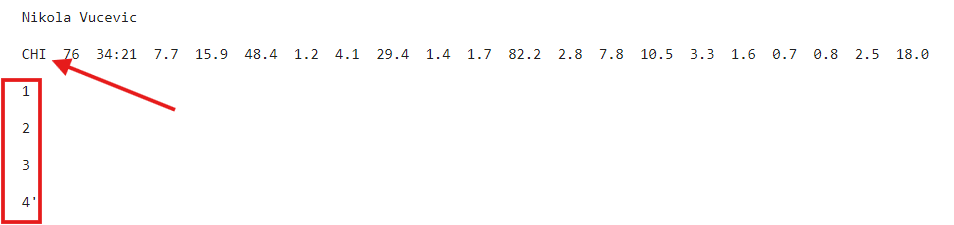

## Save Text in a .txt File

To save the extracted text into a .txt file use the code segment below.

% Specify the file name (e.g., 'extracted_text.txt')
fileName = 'NBA.txt';

% Open the file for writing
fileID = fopen(fileName, 'w');

% Write the extracted text to the file
fprintf(fileID,'%s\n', new);

% Close the file
fclose(fileID);

 

## Clean Data in .txt File

Read the newly created .txt file using **readcell() **to create a cell array**. **In this case, you will need to use readcell('NBA.txt', 'Delimiter', 'space'). 

Write the function in the code block below and store the output in a variable called **Data.**

% Read the .txt file and store in the appropriate variable
Data = readcell('NBA.txt', 'Delimiter', 'space')

Data = 105x1 cell array
    {'Player  Team  G  Min  FGM  FGA  FG%  3PM  3PA  3P%  FTM  FTA  FT%  OR  DR  Reb  Ast  TO  Stl  Blk  PF   Pts'     }
    {'Luka Doncic'                                                                                                     }
    {'DAL  70  37:29  11.5  23.6  48.7  4.1  10.6  38.2  6.8  8.7  78.6  0.8  8.4  9.2  9.8  4.0  1.4  0.5  2.1  33.9' }
    {'Giannis Antetokounmpo'                                                                                           }
    {'MIL  73  35:10  11.5  18.8  61.1  0.5  1.7  27.4  7.0  10.7  65.7  2.7  8.8  11.5  6.5  3.4  1.2  1.1  2.9  30.4'}
    {'Shai Gilgeous-Alexander'                                                                                         }
    {'OKC  75  34:02  10.6  19.8  53.5  1.3  3.6  35.3  7.6  8.7  87.4  0.9  4.7  5.5  6.2  2.2  2.0  0.9  2.5  30.1'  }
    {'Jalen Brunson'                                                                                                   }
    {'NY

The variable **Data **still has the same errors as before; therefore, you need to extract the information in it and reorganize it. You only need to extract information for the first 20 players.

Begin by extracting all the players names and save them in a one column cell array with 20 rows. In the code block below, fill in the missing inputs in the **cell() **function to make the cell array. 

% Create a column array with 50 rows to extract the players names
allNames = cell(20,1);

% Extract names from every even numbered row
for i = 2:2:40
    allNames(i) = Data(i);
end

% Removes all empty cells in the cell array allNames
allNames = allNames(~cellfun('isempty', allNames));

 

Now repeat the same procedure as above to have each of the players stats in a cell array. Fill in the missing inputs in the code block below. 

% Create a column array with 20 rows to extract the stats
allstats = cell(20,1);

% Extract stats from all odd numbered rows starting at 3.
for i = 3:2:41
    allstats(i) = Data(i);
end

% Fill in the missing inputs to remove the empty cells from the array allstats
allstats = allstats(~cellfun('isempty', allstats))

allstats = 20x1 cell array
    {'DAL  70  37:29  11.5  23.6  48.7  4.1  10.6  38.2  6.8  8.7  78.6  0.8  8.4  9.2  9.8  4.0  1.4  0.5  2.1  33.9' }
    {'MIL  73  35:10  11.5  18.8  61.1  0.5  1.7  27.4  7.0  10.7  65.7  2.7  8.8  11.5  6.5  3.4  1.2  1.1  2.9  30.4'}
    {'OKC  75  34:02  10.6  19.8  53.5  1.3  3.6  35.3  7.6  8.7  87.4  0.9  4.7  5.5  6.2  2.2  2.0  0.9  2.5  30.1'  }
    {'NY  77  35:24  10.3  21.4  47.9  2.7  6.8  40.1  5.5  6.5  84.7  0.6  3.1  3.6  6.7  2.4  0.9  0.2  1.9  28.7'   }
    {'PHO  75  37:13  10.0  19.1  52.3  2.2  5.4  41.3  4.8  5.6  85.6  0.5  6.1  6.6  5.0  3.3  0.9  1.2  1.8  27.1'  }
    {'PHO  68  35:59  9.4  19.2  49.2  2.2  6.1  36.4  6.0  6.7  88.6  0.8  3.7  4.5  6.9  2.6  0.9  0.4  3.0  27.1'   }
    {'BOS  74  35:45  9.1  19.3  47.1  3.1  8.2  37.6  5.6  6.7  83.3  0.9  7.2  8.1  4.9  2.5  1.0  0.6  2.0  26.9'   }
    {'SAC  74  35:56  9.7  20.9  46.5  2.9  7.8  36.9  4.2  5.7  73.8  0.9  3.7  4.6  5.6  2.6  2.0  0.4  2.6  26.6'   }
    {

## Store Cleaned Data

Save the new cell array as a .csv.

- Convert the cell array to table

- Use **writetable()** to make the a .csv file named 'clean.csv'

newTable = cell2table([allNames allstats]);
writetable(newTable, 'clean.csv');
Final = readtable('clean.csv')

Final = 20x22 table
        Var1                   Var2               Var3      Var4       Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22
    ____________    __________________________    ____    _________    ____    ____    ____    ____    ____    _____    _____    _____    _____    _____

Now add names to each of the a variables above. 

% Specify the new variable names
newNames = {'FirstName', 'LastName,Team', 'G', 'Min', 'FGM', 'FGA', 'FG%','3PM','3PA','3P%', 'FTM', 'FTA', 'FT%', 'OR', 'DR','Reb', 'Ast', 'TO', 'Stl', 'Blk', 'PF', 'Pts'};

% Rename the variables
Final = renamevars(Final, 1:width(Final), newNames)

Final = 20x22 table
     FirstName            LastName,Team           G        Min       FGM     FGA     FG%     3PM    3PA     3P%     FTM    FTA     FT%     OR     DR     Reb     Ast    TO     Stl    Blk    PF     Pts 
    ____________    __________________________    __    _________    ____    ____    ____    ___    ____    ____    ___    ____    ____    ___    ___ 

## Summary

In this lesson, you were introduced to web scraping and the functions needed to scrape data from a website. While working through this lesson, you might have noticed that it mostly involved cleaning the data scraped from the website. Therefore, it is recommended to select websites with easy-to-read tables to reduce the amount of work required to get your data ready for analysis.